# EE141 Digital Signal Processing

# Lab 2: The Discrete Time Fourier Transform

# Lab Section: 022

# Name: Buddy Ugwumba SID: 862063029

## Objective:

Verification of properties related to the D.T.F.T 

## Results:

Successful analyitical and numerical computation of the DTFT for a right-sided signal . The same properties were then applied to a various linear transformations and the convolution of said signals  Additiaonlly, a deepended understanding of how to interpret the graph of D.T.F.T. Specifically, how the magnitude plots identify which frequencies would pass through and which ones would be attenuated if such a system was used as a filter. Moreover, the phase told me how all the frequencies align in time. 

## Procedure:

### a) Analytically compute $X\left(e^{j\omega } \right)$ using:

### 
$$X\left(e^{j\omega } \right)\sum_{n=-\infty }^{\infty } {x\left\lbrack n\right\rbrack e}^{j\omega n}$$


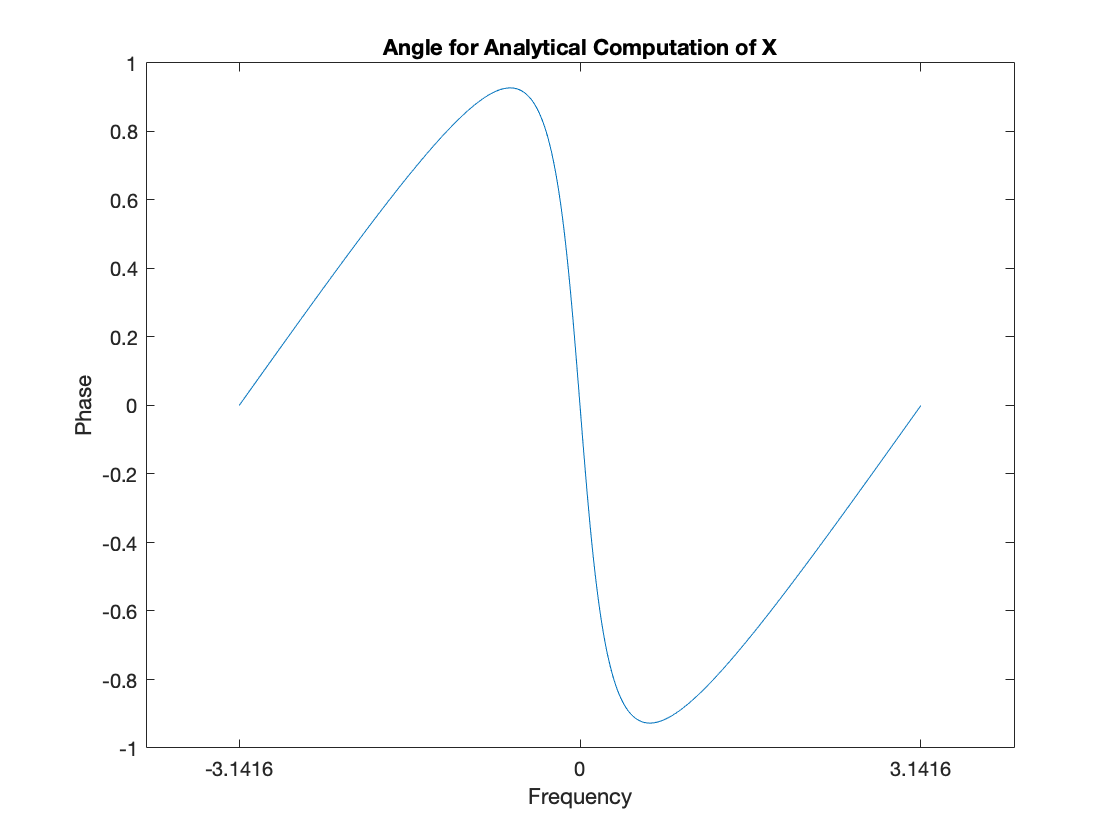

% Create a vector in MATLAB by sampling the omega interval from [-pi,pi]
% Using K uniform points for some large K
% and Evaluate for each sample point
K = 500;
w_k = -pi:(2*pi/K):pi;
% Recall that x[n] = 0.8^n*u[n]. 
% This is a geometric series. Recall that the D.T.F.T. for a geometric 
% series whos alpha is less than one is always 1/1-ratio*exp(jwn))
X = 1./(1-0.8.*exp(-1i*w_k));
%plot 
plot(w_k,angle(X))
set(gca,'XTick',-2*pi:pi:2*pi)
title('Angle for Analytical Computation of X')
xlabel('Frequency');
ylabel('Phase');

### b) For each $w_k$, numerically compute $\overset{~}{X} \left(e^{-j\omega_k } \right)$using:

### 
$$X\left(e^{j\omega } \right)\sum_{n=0}^{\infty } {x\left\lbrack n\right\rbrack e}^{j\omega n}$$


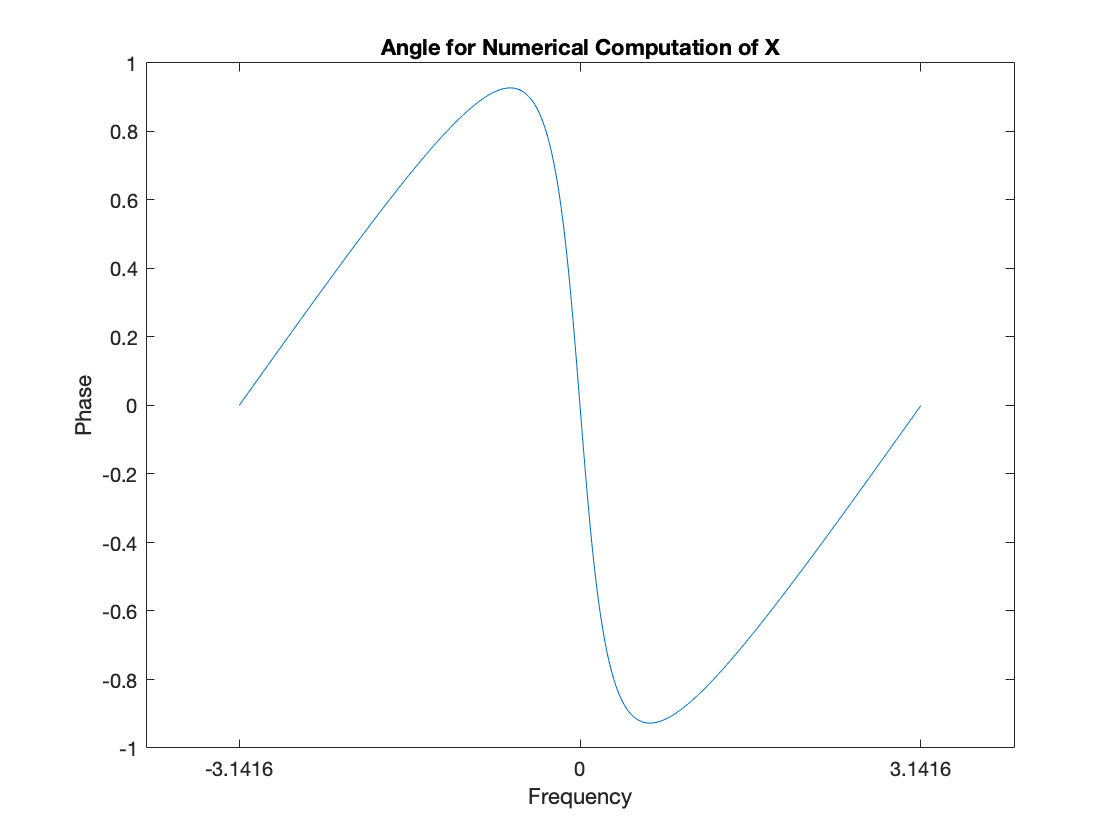

%Pick a large enough N to satisify 0.9^N ~ 0.
N = 100;
n = 0:N;
for k = 1:K+1
    x(k) = sum((0.8.^(n)).*exp(-1i*w_k(k).*n));
end
plot(w_k, angle(x))
set(gca, 'XTick', -2*pi:pi:2*pi);
title('Angle for Numerical Computation of X')
xlabel('Frequency')
ylabel('Phase')

### c) Plot $|X\left(e^{j\omega_k } \right)|$and $|\overset{~}{X} \left(e^{j\omega_k } \right)|$on the same graph using different colors

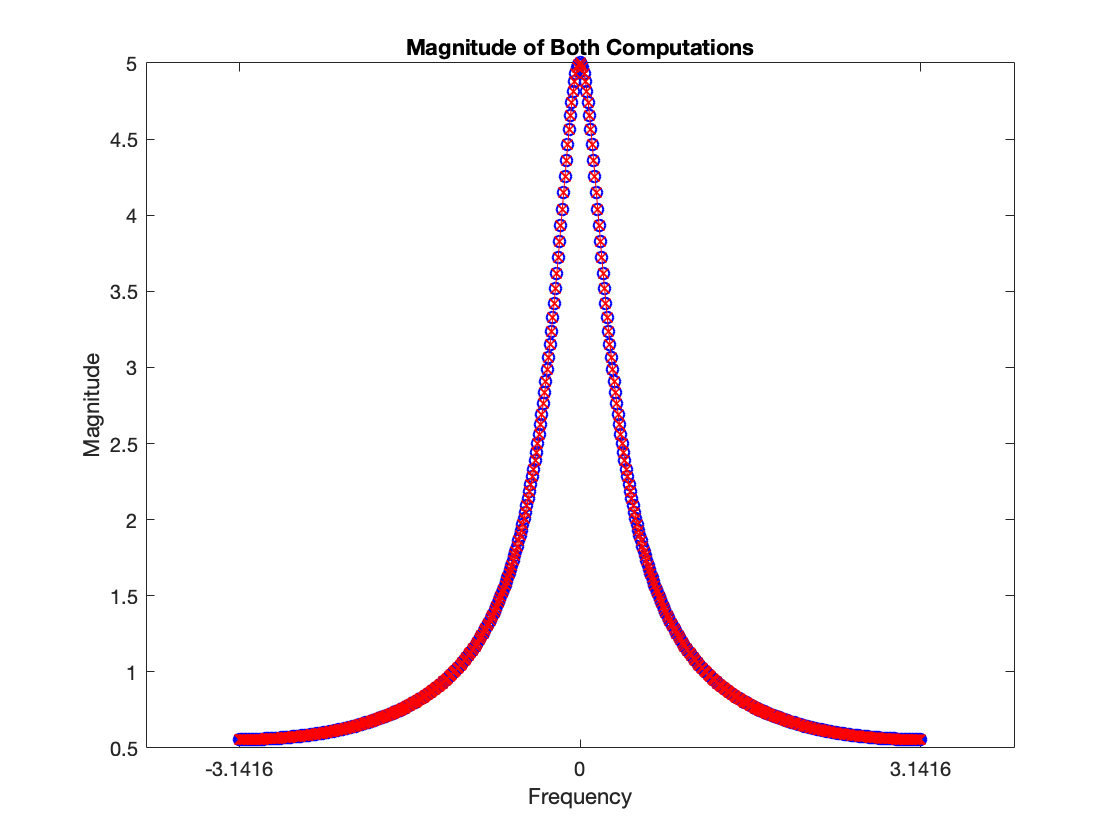

plot(w_k,abs(X), 'b-o')
hold on
plot(w_k,abs(x), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Magnitude of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

### d) Using the same $N$ and $K$, repeat a through c for $Y\left(e^{j\omega } \right)$ and its approximation $\overset{~}{Y} \left(e^{j\omega } \right)$

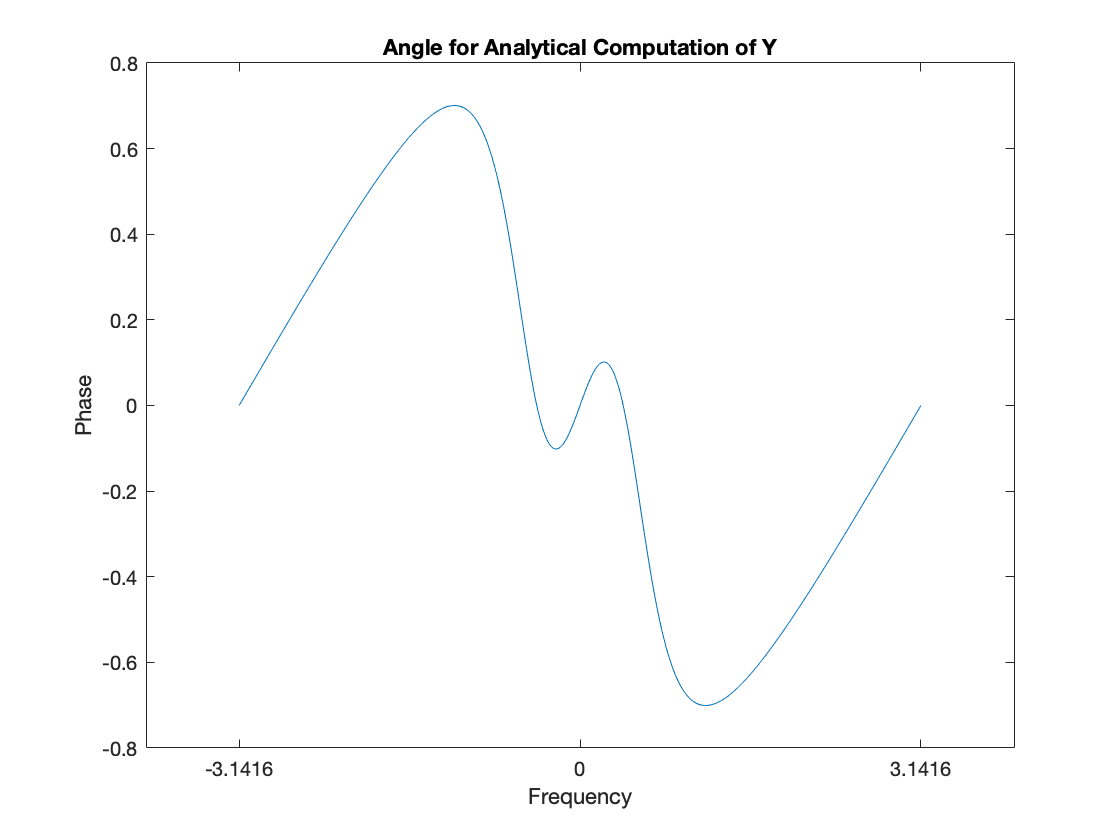

K = 500;
w_k = -pi:(2*pi/K):pi;
Y = 0.5.*((1./(1-0.7.*exp(1i*((pi/6)-w_k)))) + (1./(1-0.7.*exp(-1i*((pi/6)+w_k)))));
plot(w_k,angle(Y))
set(gca,'XTick',-2*pi:pi:2*pi)
title('Angle for Analytical Computation of Y')
xlabel('Frequency');
ylabel('Phase');

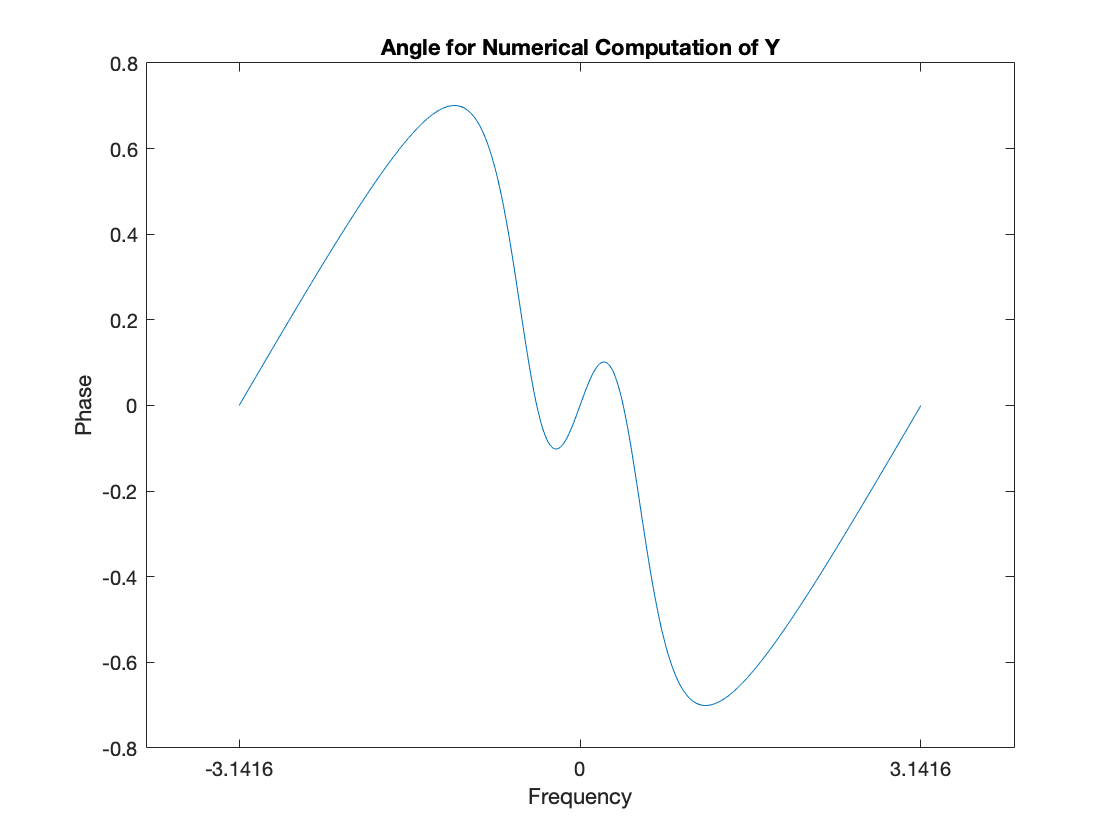

%Pick a large enough N to satisify 0.9^N ~ 0.
N = 100;
n = 0:N;
for k = 1:K+1
    y(k) = sum((0.7.^(n).*cos((pi.*n)/6)).*exp(-1i*w_k(k).*n));
end
plot(w_k, angle(y))
set(gca, 'XTick', -2*pi:pi:2*pi);
title('Angle for Numerical Computation of Y')
xlabel('Frequency')
ylabel('Phase')

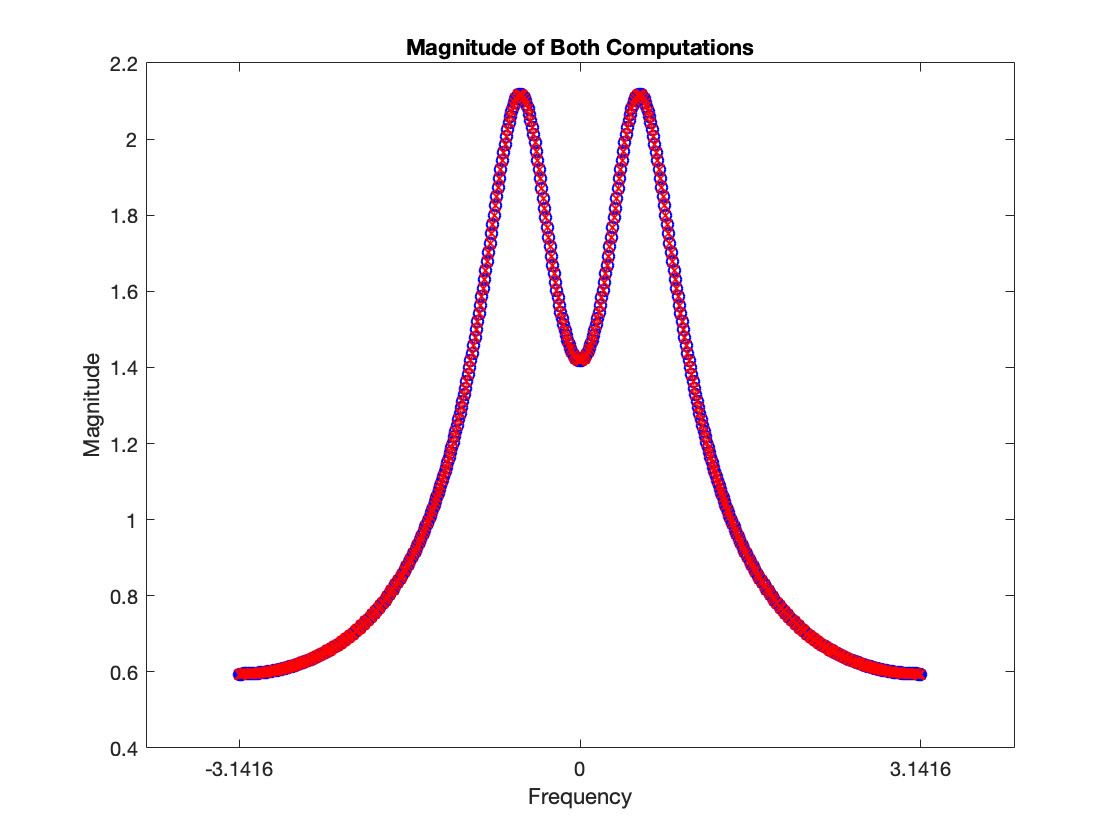

plot(w_k,abs(Y), 'b-o')
hold on
plot(w_k,abs(y), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Magnitude of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

### e) Let $x\left\lbrack n\right\rbrack =2x\left\lbrack n\right\rbrack +3y\left\lbrack n\right\rbrack$

#### 1) Analytically compute $Z\left(e^{j\omega } \right)$ using $X\left(e^{j\omega } \right),Y\left(e^{j\omega } \right),$ and the relevant property of DTFT.

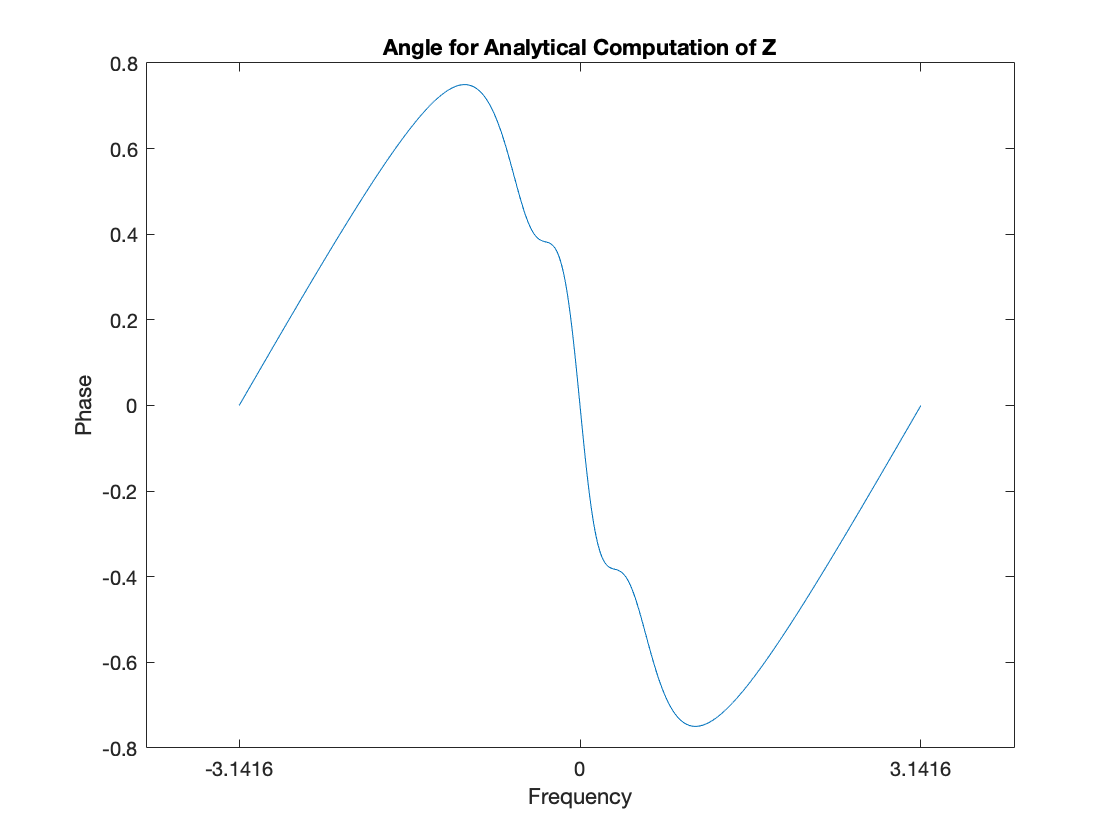

Z = 2*X + 3*Y;
plot(w_k,angle(Z))
set(gca,'XTick',-2*pi:pi:2*pi)
title('Angle for Analytical Computation of Z')
xlabel('Frequency');
ylabel('Phase');

#### 3) Numerically computer $\overset{~}{Z} \left(e^{j\omega_n } \right)$ using the truncated sum in (2) with $x\left\lbrack n\right\rbrack$

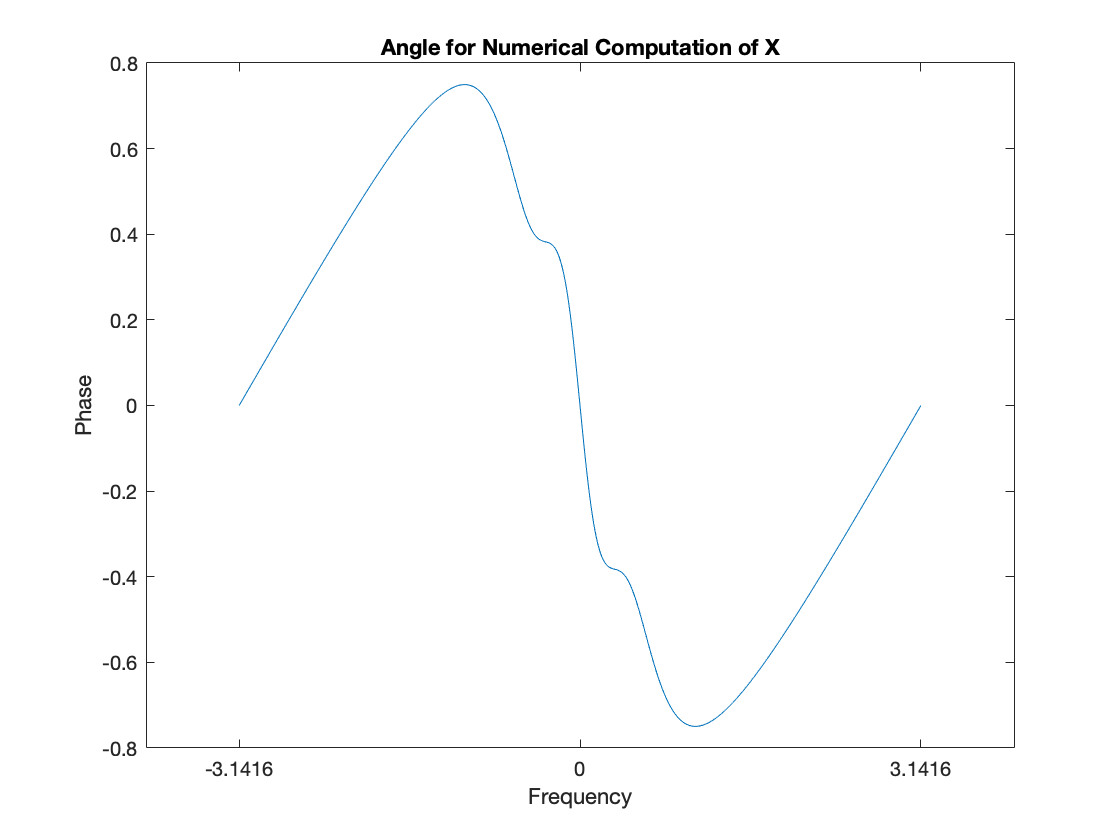

%Pick a large enough N to satisify 0.9^N ~ 0.
N = 100;
n = 0:N;
for k = 1:K+1
    z(k) = sum((2*(0.8.^(n)) + 3*(0.7.^(n).*cos((pi.*n)/6))).*exp(-1i*w_k(k).*n));
end
plot(w_k, angle(z))
set(gca, 'XTick', -2*pi:pi:2*pi);
title('Angle for Numerical Computation of X')
xlabel('Frequency')
ylabel('Phase')

#### 4) Plot $|Z\left(e^{j\omega_k } \right)|$and $|\overset{~}{Z} \left(e^{j\omega_k } \right)|$on the same graph. Do they look same

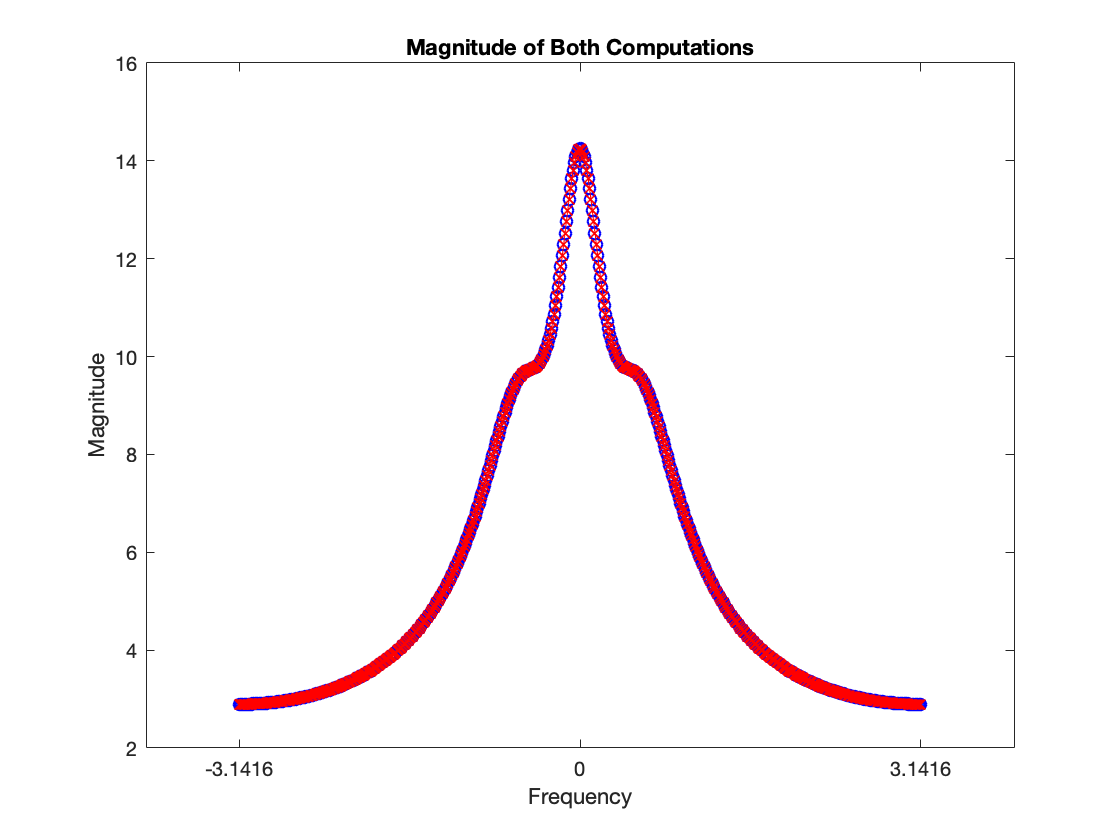

plot(w_k,abs(Z), 'b-o')
hold on
plot(w_k,abs(z), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Magnitude of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

Yes, the graphs looks the same

#### 5) Plot $|\angle Z\left(e^{{j\omega }_k } \right)$ and $\angle \overset{~}{Z} \left(e^{j\omega_k } \right)$ on the same graph. Do they look the same?

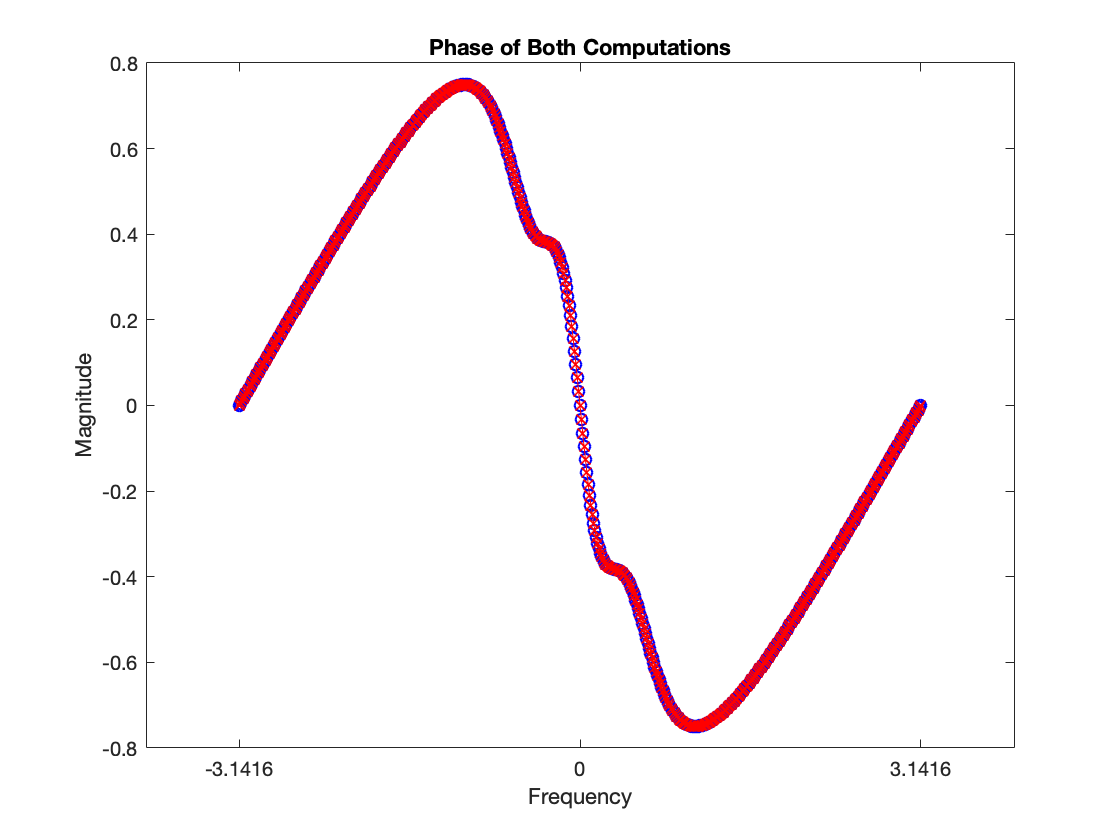

plot(w_k,angle(Z), 'b-o')
hold on
plot(w_k,angle(z), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Phase of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

Yes the graphs look the same

### f) Repeat e with $z\left\lbrack n\right\rbrack =x\left\lbrack n-6\right\rbrack$.

#### 1) Analytically compute $Z\left(e^{j\omega } \right)$ using $X\left(e^{j\omega } \right),Y\left(e^{j\omega } \right),$ and the relevant property of DTFT.

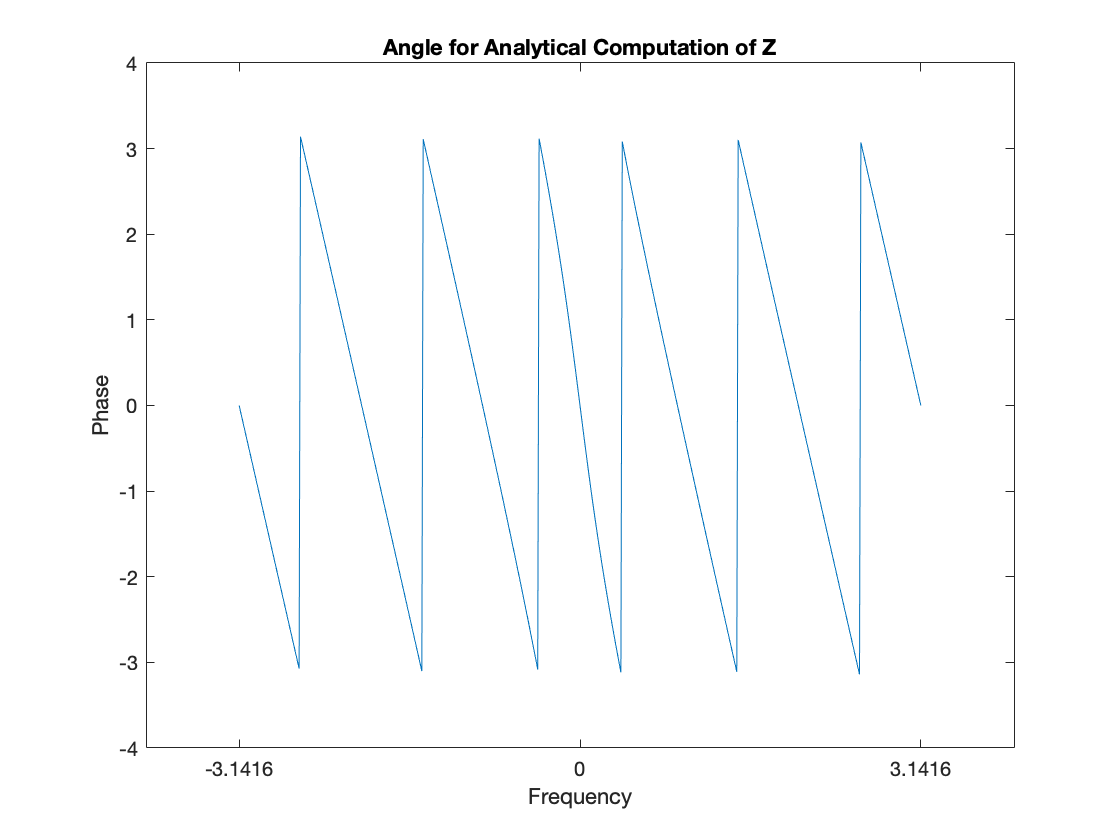

K = 500;
w_k = -pi:(2*pi/K):pi;
N = 100;
n = 6:N;
X = 1./(1-0.8.*exp(-1i*w_k));
Z = X.*exp(-1i*w_k*6);
plot(w_k,angle(Z))
set(gca,'XTick',-2*pi:pi:2*pi)
title('Angle for Analytical Computation of Z')
xlabel('Frequency');
ylabel('Phase');

#### 3) Numerically computer $\overset{~}{Z} \left(e^{j\omega_n } \right)$ using the truncated sum in (2) with $x\left\lbrack n\right\rbrack$

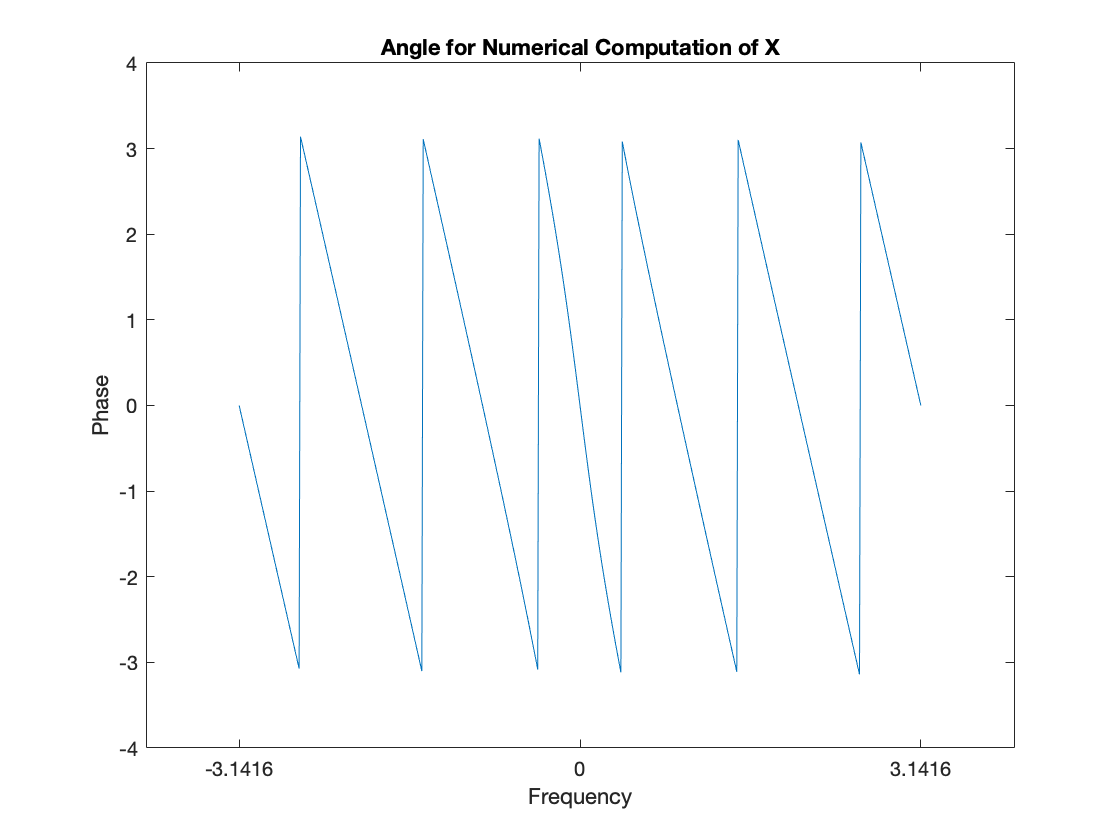

%Pick a large enough N to satisify 0.9^N ~ 0.
N = 100;
n = 6:N;
for k = 1:K+1
    z(k) = sum((0.8.^(n-6).*exp(-1i*w_k(k).*n)));
end

plot(w_k, angle(z))
set(gca, 'XTick', -2*pi:pi:2*pi);
title('Angle for Numerical Computation of X')
xlabel('Frequency')
ylabel('Phase')

#### 4) Plot $|Z\left(e^{j\omega_k } \right)|$and $|\overset{~}{Z} \left(e^{j\omega_k } \right)|$on the same graph. Do they look same

plot(w_k,abs(Z), 'b-o')
hold on
plot(w_k,abs(z), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Magnitude of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

Yes, the graphs looks the same

#### 5) Plot $|\angle Z\left(e^{{j\omega }_k } \right)$ and $\angle \overset{~}{Z} \left(e^{j\omega_k } \right)$ on the same graph. Do they look the same?

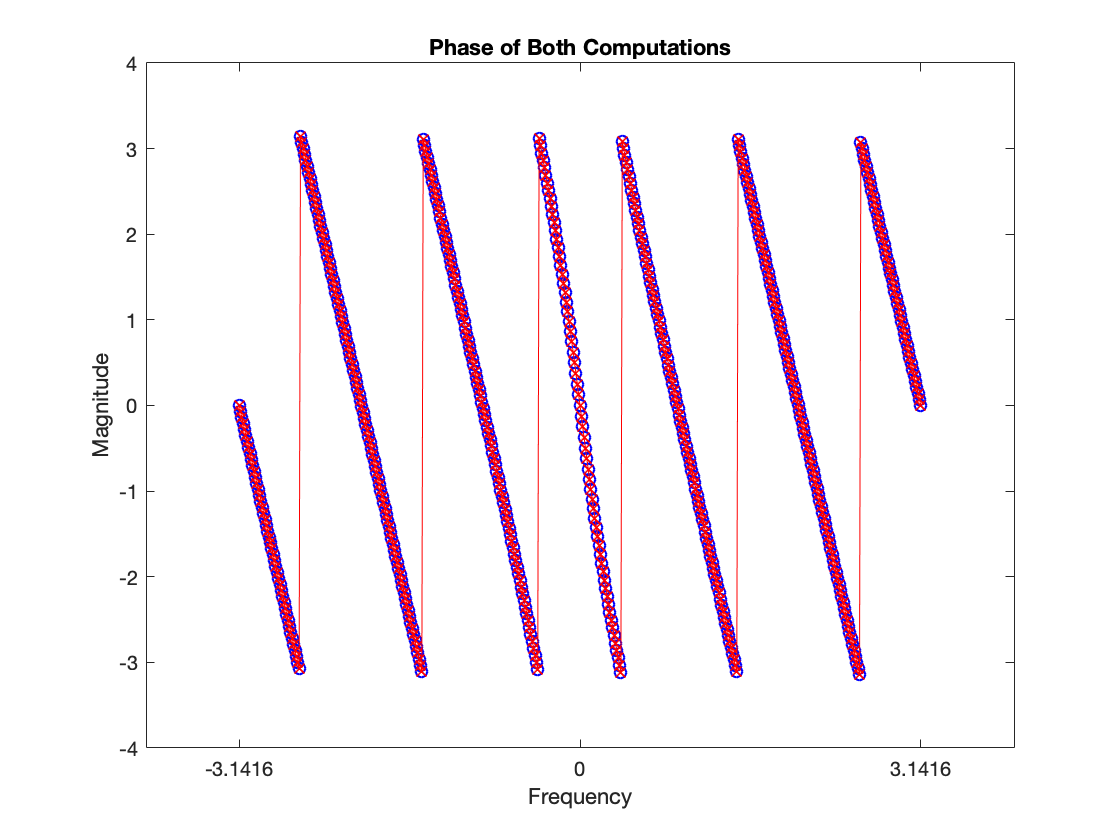

plot(w_k,angle(Z), 'b-o')
hold on
plot(w_k,angle(z), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Phase of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

Yes the graphs look the same

### g) Repeat e with $z\left\lbrack n\right\rbrack =e^{j\frac{\pi }{2}n} x\left\lbrack n\right\rbrack$

#### 1) Analytically compute $Z\left(e^{j\omega } \right)$ using $X\left(e^{j\omega } \right),Y\left(e^{j\omega } \right),$ and the relevant property of DTFT.

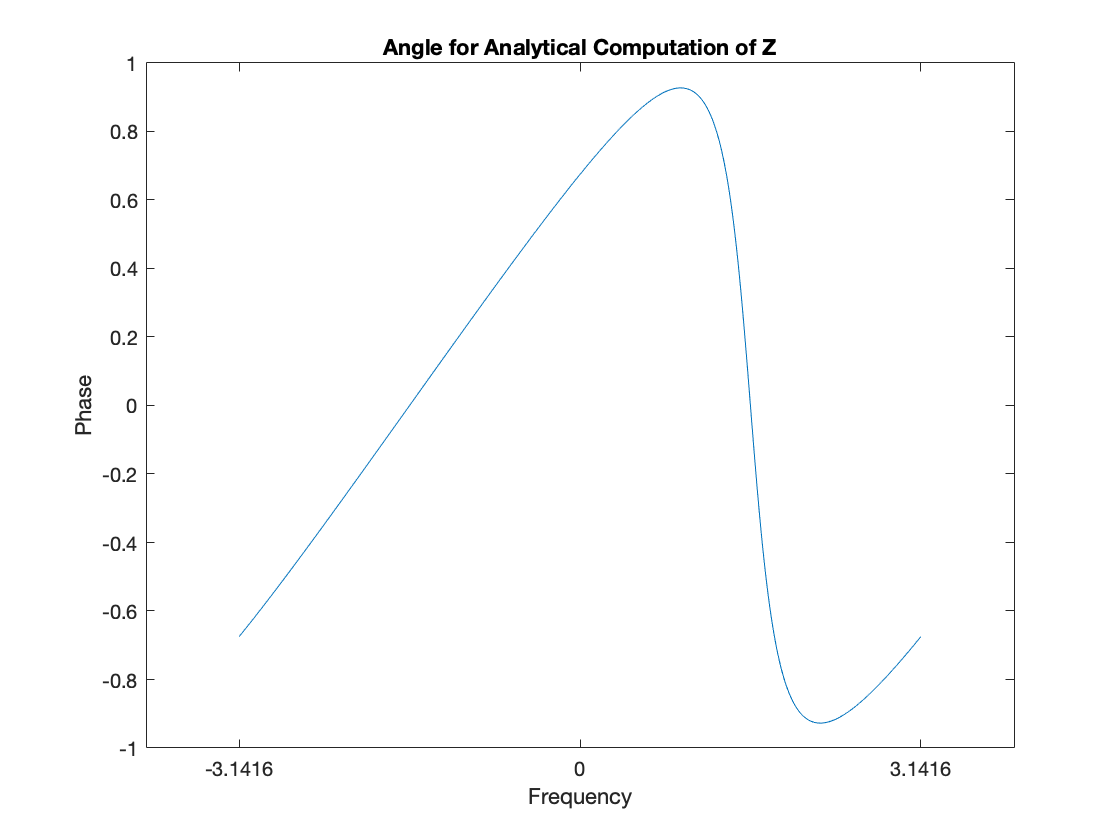

X = 1./(1-0.8.*exp(-1i*(w_k-pi/2)));
Z = X;
plot(w_k,angle(Z))
set(gca,'XTick',-2*pi:pi:2*pi)
title('Angle for Analytical Computation of Z')
xlabel('Frequency');
ylabel('Phase');

#### 3) Numerically computer $\overset{~}{Z} \left(e^{j\omega_n } \right)$ using the truncated sum in (2) with $x\left\lbrack n\right\rbrack$

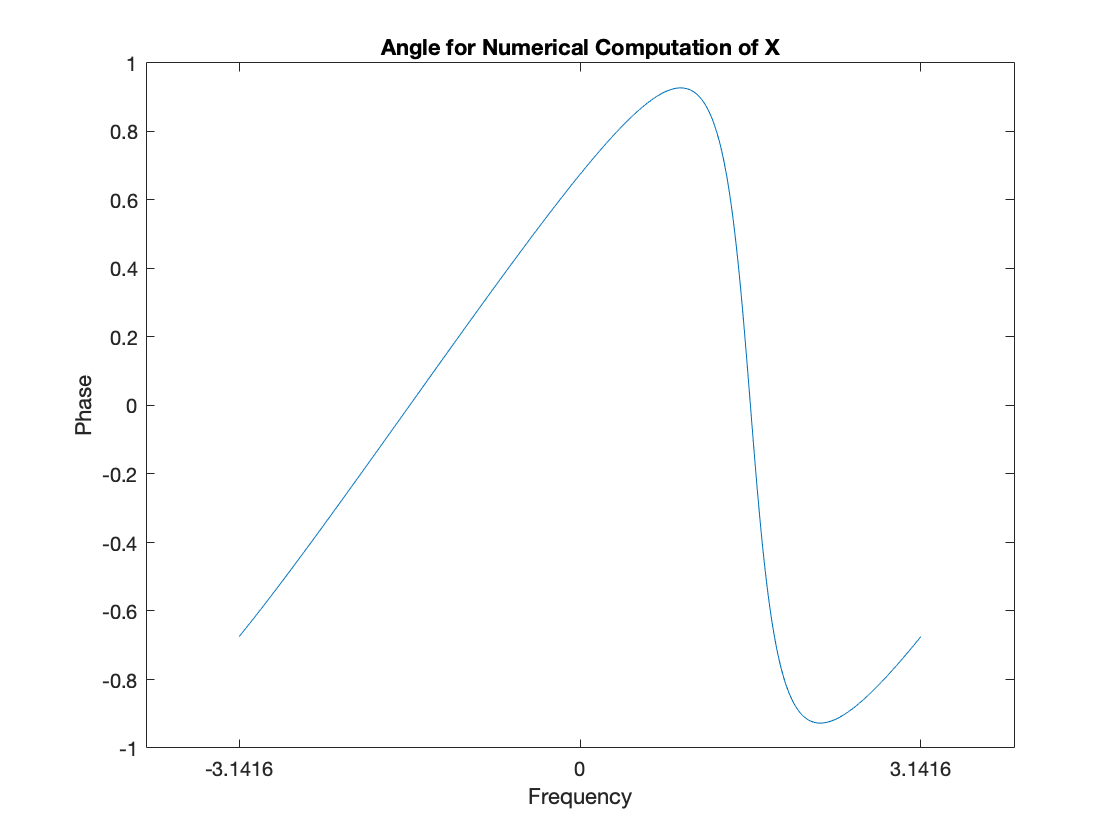

%Pick a large enough N to satisify 0.9^N ~ 0.
N = 100;
n = 0:N;
for k = 1:K+1
    z(k) = sum((0.8.^(n).*exp(1i*(pi/2.*n)).*exp(-1i*w_k(k).*n)));
end

plot(w_k, angle(z))
set(gca, 'XTick', -2*pi:pi:2*pi);
title('Angle for Numerical Computation of X')
xlabel('Frequency')
ylabel('Phase')

#### 4) Plot $|Z\left(e^{j\omega_k } \right)|$and $|\overset{~}{Z} \left(e^{j\omega_k } \right)|$on the same graph. Do they look same

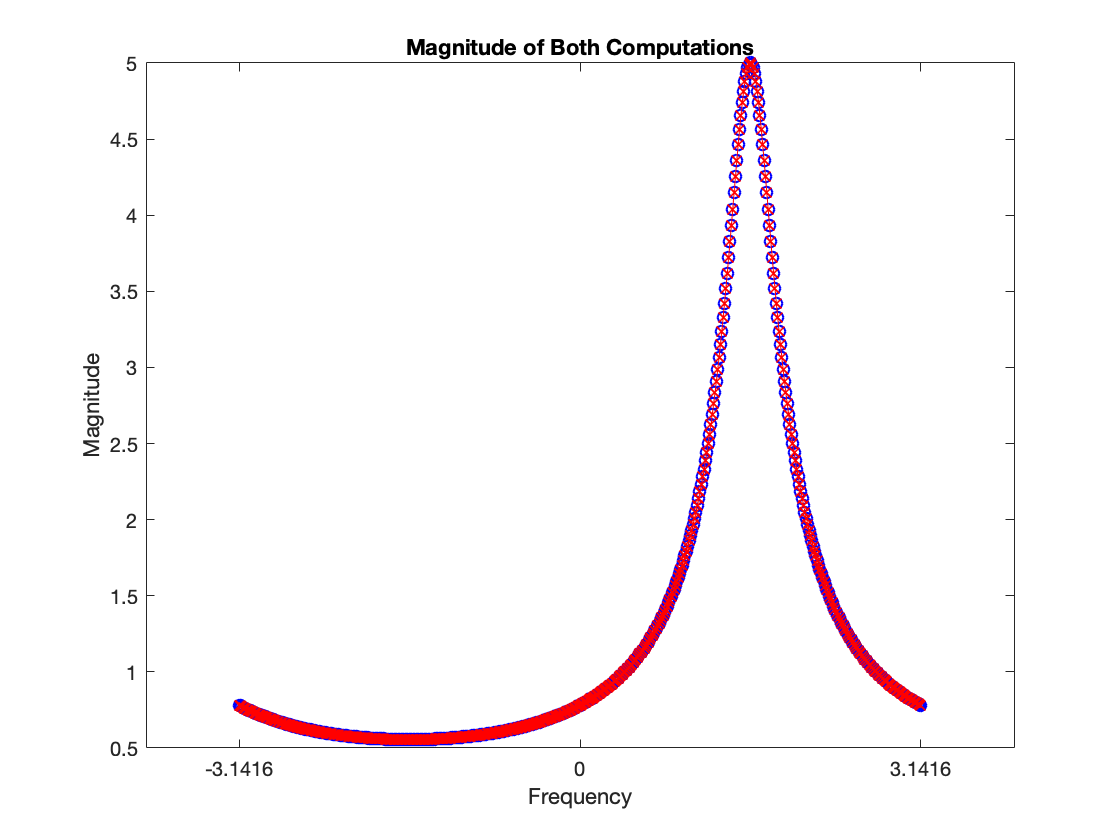

plot(w_k,abs(Z), 'b-o')
hold on
plot(w_k,abs(z), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Magnitude of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

Yes, the graphs looks the same

#### 5) Plot $|\angle Z\left(e^{{j\omega }_k } \right)$ and $\angle \overset{~}{Z} \left(e^{j\omega_k } \right)$ on the same graph. Do they look the same?

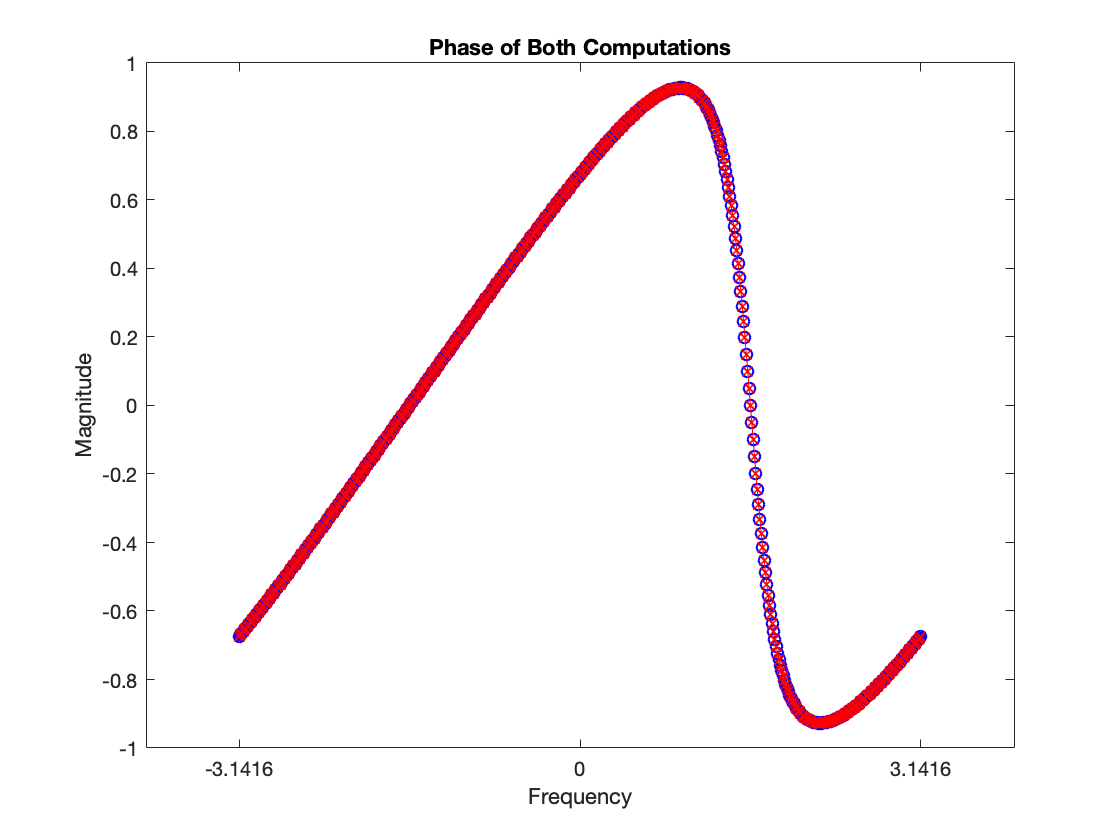

plot(w_k,angle(Z), 'b-o')
hold on
plot(w_k,angle(z), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Phase of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

Yes the graphs look the same

### h) Repeate e with $z\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \star y\left\lbrack n\right\rbrack$

#### 1) Analytically compute $Z\left(e^{j\omega } \right)$ using $X\left(e^{j\omega } \right),Y\left(e^{j\omega } \right),$ and the relevant property of DTFT.

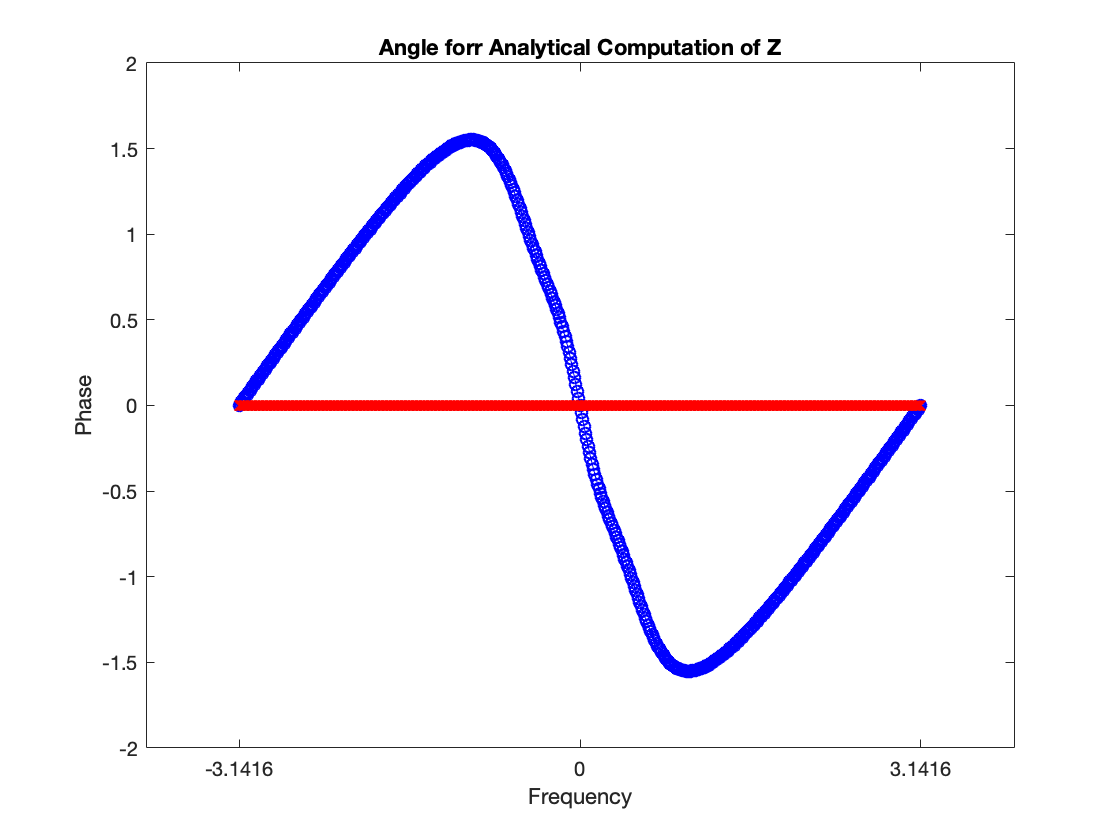

X = 1./(1-0.8.*exp(-1i*w_k));
Z = X.*Y;
%plot(w_k,angle(Z))
set(gca,'XTick',-2*pi:pi:2*pi)
title('Angle forr Analytical Computation of Z')
xlabel('Frequency');
ylabel('Phase');

#### 3) Numerically computer $\overset{~}{Z} \left(e^{j\omega_n } \right)$ using the truncated sum in (2) with $x\left\lbrack n\right\rbrack$

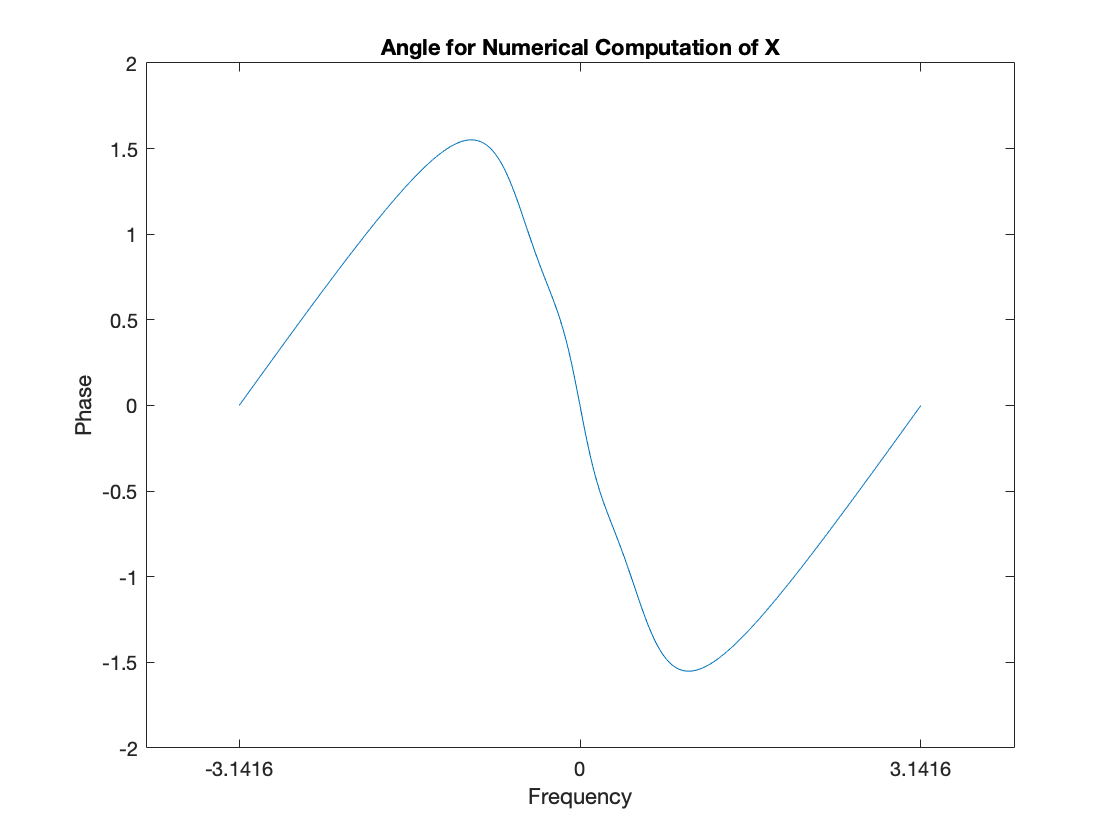

%Pick a large enough N to satisify 0.9^N ~ 0.
N = 100;
n = 0:N;
for k = 1:K+1
    x = 0.8.^(n).*exp(-1i*w_k(k).*n);
    y = 0.7.^(n).*cos((pi.*n)/6).*exp(-1i*w_k(k).*n);
    z(k) = sum(conv(x,y,'full'));
end
plot(w_k, angle(z))
set(gca, 'XTick', -2*pi:pi:2*pi);
title('Angle for Numerical Computation of X')
xlabel('Frequency')
ylabel('Phase')

#### 4) Plot $|Z\left(e^{j\omega_k } \right)|$and $|\overset{~}{Z} \left(e^{j\omega_k } \right)|$on the same graph. Do they look same

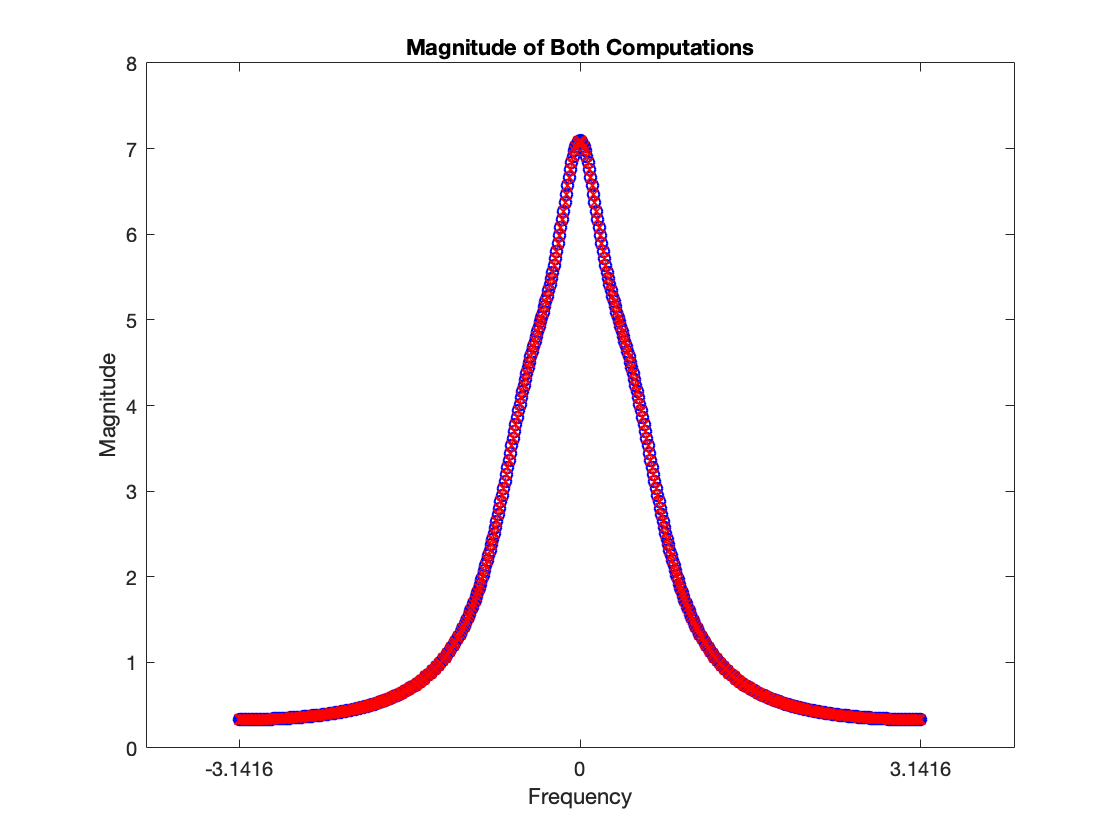

plot(w_k,abs(Z), 'b-o')
hold on
plot(w_k,abs(z), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Magnitude of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

Yes, the graphs looks the same

#### 5) Plot $|\angle Z\left(e^{{j\omega }_k } \right)$ and $\angle \overset{~}{Z} \left(e^{j\omega_k } \right)$ on the same graph. Do they look the same?

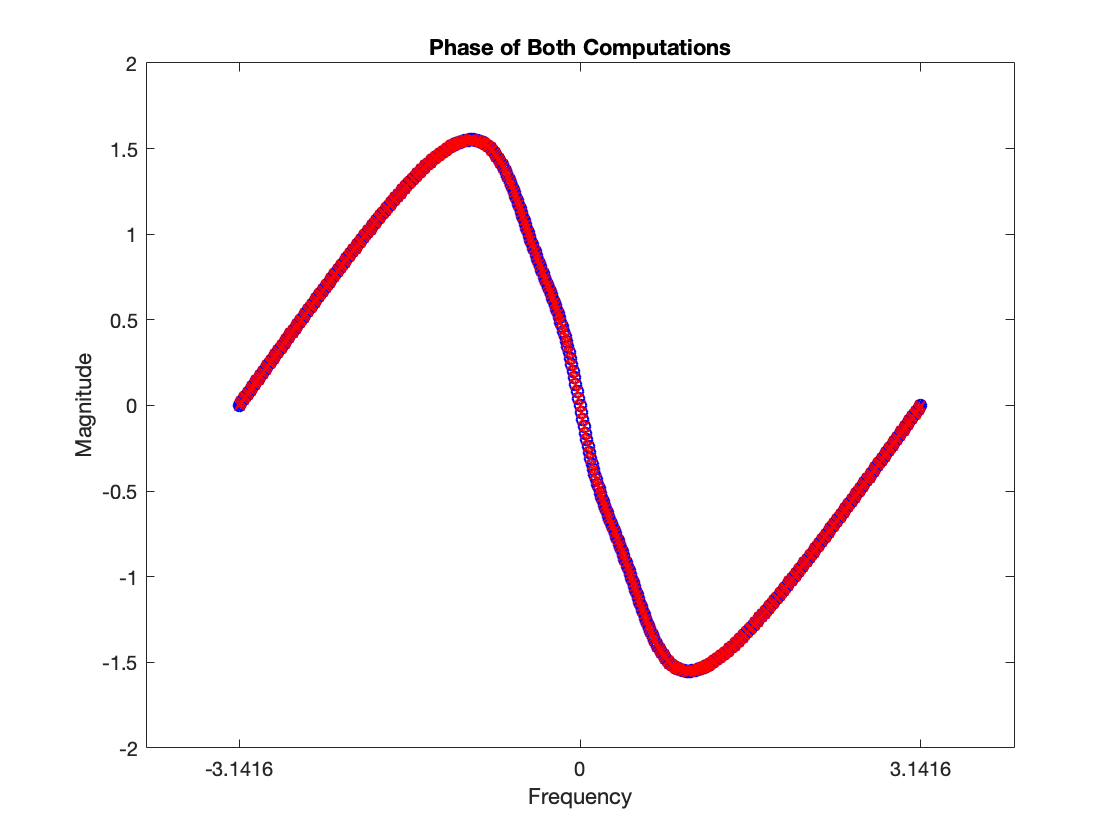

plot(w_k,angle(Z), 'b-o')
hold on
plot(w_k,angle(z), 'r-x')
hold off
set(gca, 'XTick', -2*pi:pi:2*pi)
title('Phase of Both Computations')
xlabel('Frequency')
ylabel('Magnitude')

Yes the graphs look the same

;

2